# Геометрические преобразования изображений

## Обрезка

Обрезать можно с помощью функции `imcrop`. У нее 2 варианта применения:

- Вызвать функцию `imcrop(I)`. Тогда обрезка изображения `I` будет интерактивной

- Вызвать с аргументом `imcrop(I,rect)`, где `I` - исходное изображение, а `rect` - прямоугольник, который надо оставить. Прямоугольник задается относительно левого верхнего края изображения.

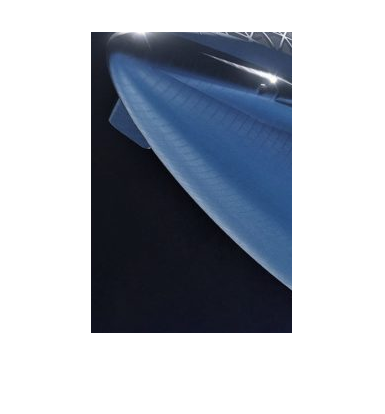

I = imread("BFS_rocket.jpg");
Icroped_1 = imcrop(I);
rect = [30, 30, 200, 300];
Icroped_2 = imcrop(I, rect);
imshow(Icroped_2)

## Изменение размера

Изменение размера происходит с помощью функции `imresize`. В качестве аргумента можно задавать масштаб `imresize(I, scale)` или требуемые размеры в пикселях` imresize(I, [numrows, numcols])`.

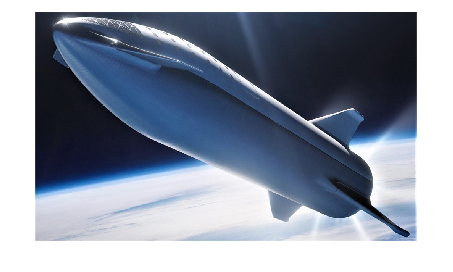

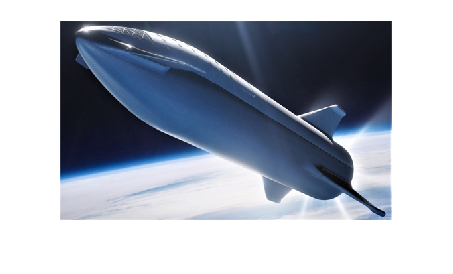

J = imresize(I, 0.5);
figure, imshow(I), figure, imshow(J)

Также задается метод интерполяции:

`"nearest"`

Стоит по умолчанию. Интерполяция по ближайшему соседу; выходному пикселю присваивается значение пикселя, который находится в пределах точки. Никакие другие пиксели не рассматриваются.

`"bilinear"`

Билинейная интерполяция; значение выходного пикселя является взвешенным средним в окружении 2 на 2

`"bicubic"`

Бикубическая интерполяция; значение выходного пикселя является взвешенным средним в окружении 4 на 4

## Поворот

Для поворота изображения используется функция `imrotate(I,angle)`. Она поворачивает изображение `I` на угол `angle` в градусах против часовой стрелки.

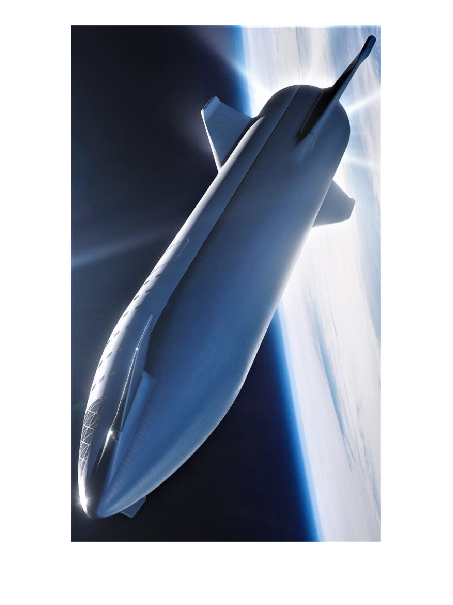

J = imrotate(I, 90);
imshow(J)

## Перемещение

Функция` imtranslate(A, translation)` переносит изображение `A` на вектор сдвига `translation`.

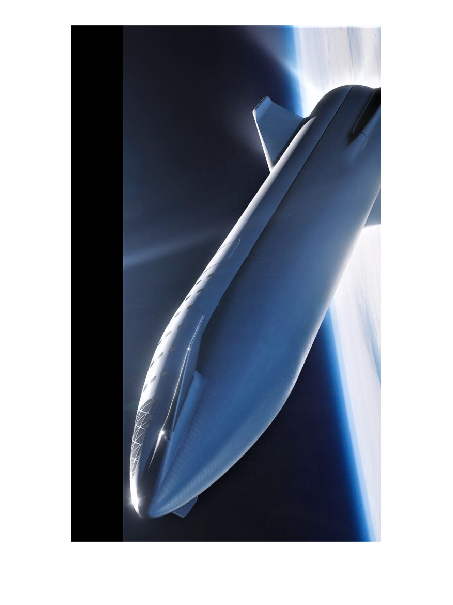

K = imtranslate(J, [100, 0]);
imshow(K)